# Lab 2 DC Motor 

clear; clc;
sim = sim('Ex2Week1Simupdate.slx');

# Below Consists of What to turn in for Final Report

### Closed Loop Step Responses 

The previous open loop simulink model was modified to represent a closed loop model. This was done by adding an output potentiometer in a feedback path that connected the output position theta to the correct input of the op-amp summing amplifier. 

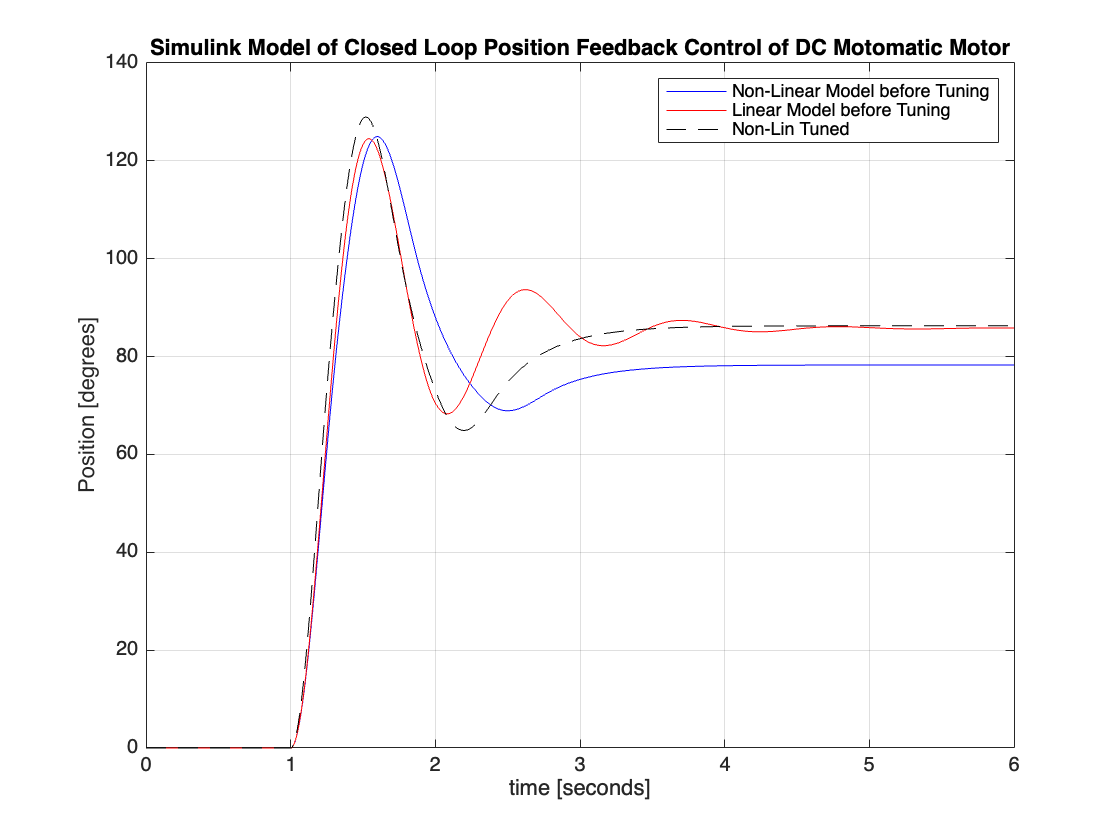

figure()
plot(sim.tout,sim.nonlinfeedback,"b")
hold on
plot(sim.tout,sim.linfeedback_Fixed,"r")
plot(sim.tout,sim.nonlinfeedback_tuned,"k--")
title("Simulink Model of Closed Loop Position Feedback Control of DC Motomatic Motor")
ylabel("Position [degrees]")
xlabel("time [seconds]")
legend("Non-Linear Model before Tuning", "Linear Model before Tuning","Non-Lin Tuned")
xlim([0 6])
grid on
hold off

### Experimental & Sim Closed Loop Step Responses 

The previous open loop simulink model w

Pos_Data = 'Experimental_PvsT_CL.xlsx' ; % Retrieves Excel File with Data 
data = readtable(Pos_Data) ; % Reads Experimental Data for CL Feedback 

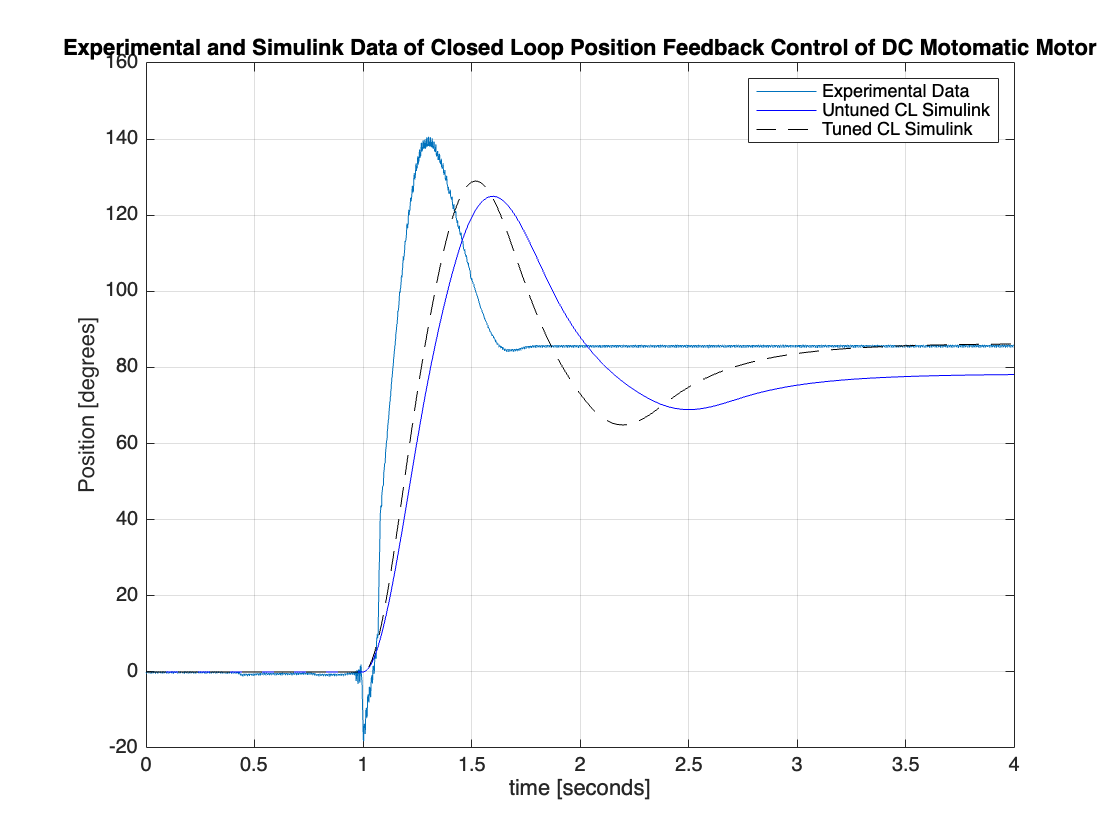

% Extract the data for plotting
time = data(:,4) ; % Time in seconds

timeArrray=table2array(time) ; 
position = data(:,5) ; % Position in Degrees
posArray = table2array(position) ;

% Plot the experimental data
figure()
plot(timeArrray, posArray)
hold on
plot(sim.tout,sim.nonlinfeedback,"b")
plot(sim.tout,sim.nonlinfeedback_tuned,"k--")
title("Experimental and Simulink Data of Closed Loop Position Feedback Control of DC Motomatic Motor")
ylabel("Position [degrees]")
xlabel("time [seconds]")
legend("Experimental Data","Untuned CL Simulink","Tuned CL Simulink")
xlim([0 4])
grid on
hold off

drop might be noise

- backemf is force

- seeing data which tells where pos is

- some discrepancy between where 

- noise from voltage signals

- spring back maybe from 

- wind up

### OL Step Response to Find Tau 

Step Response to find Tau

## Real System Step Response

The following shows the step repsonse of the DC Motor collected during lab. 

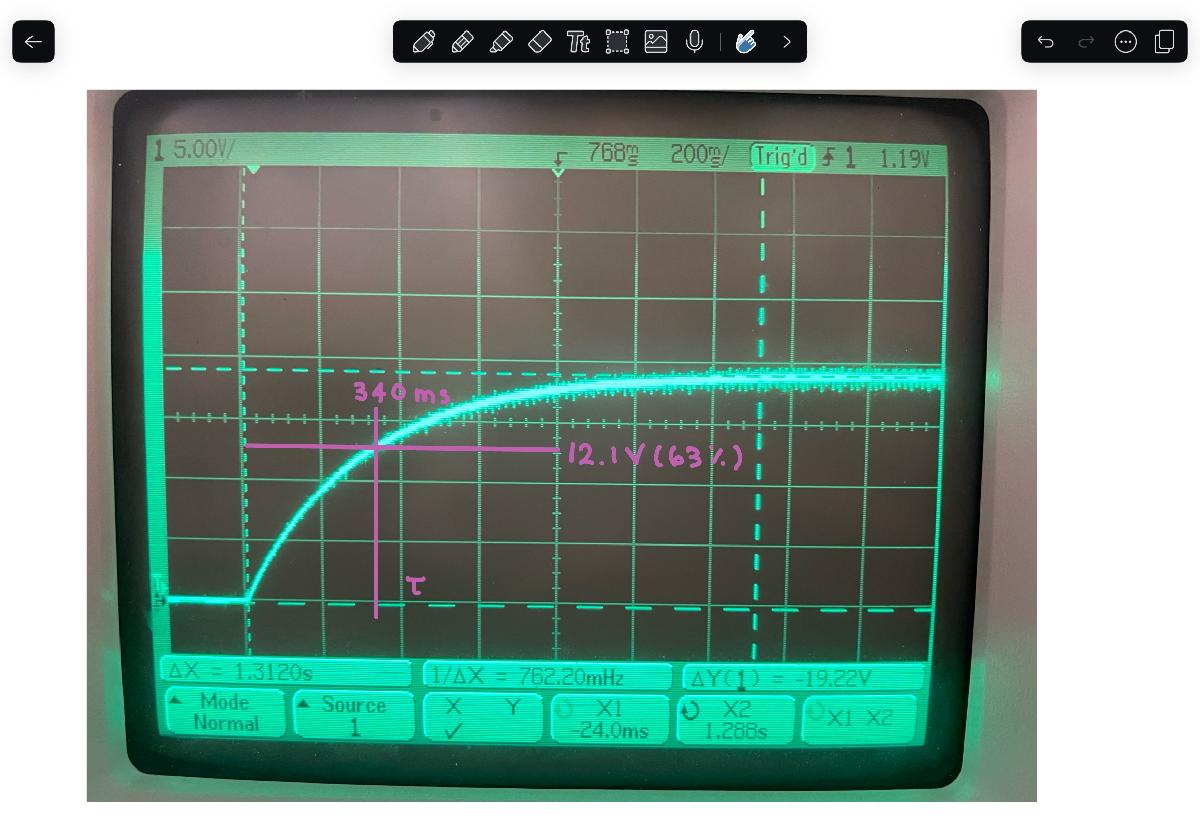

The gain is 19.22 Volts. 

Tau_Location = 0.63*19.22

Tau_Location = 12.1086

The location of the time constant, Tau, sits at 63% of the gain. This is at 12.1086 Volts. By observation, the time response sits at about 0.34 seconds into the step response curve. 

### Open Loop Step Responses

The constant, Km,lin, was determined for the linear model by making an estimate of the "average" slope of the wm vs VA data collected during lab. The linear model uses Km,lin as the motor constant. 

The constant Km for the nonlinear model was determined by finding the slope of the wm vs VA data  outside of the deadband area. 

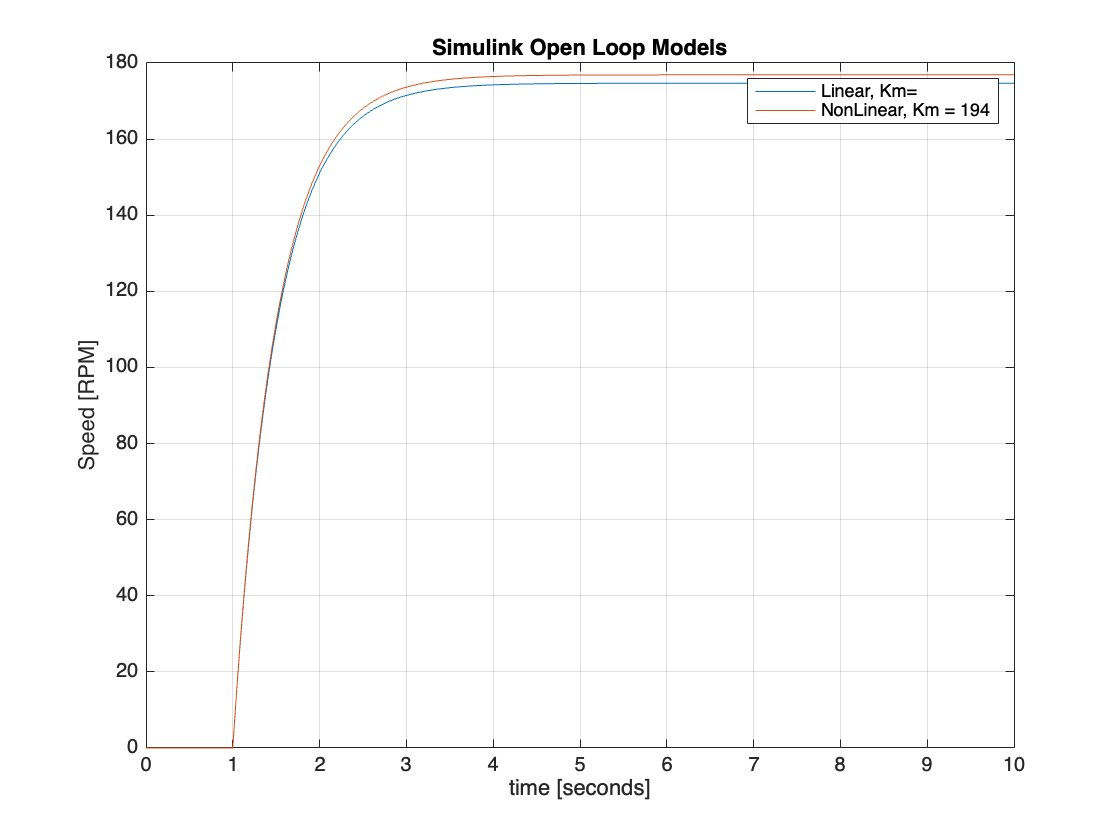

figure()
plot(sim.tout,sim.Linear)
hold on
plot(sim.tout,sim.nonlinear)
title("Simulink Open Loop Models")
ylabel("Speed [RPM]")
xlabel("time [seconds]")
legend("Linear, Km= ","NonLinear, Km = 194")
grid on
hold off